# **Explore 2-DOF Spring Mass Damper - Homogeneous response          **

In this example we're going to study the two degree of freedom (dof)  mechanical system shown below:

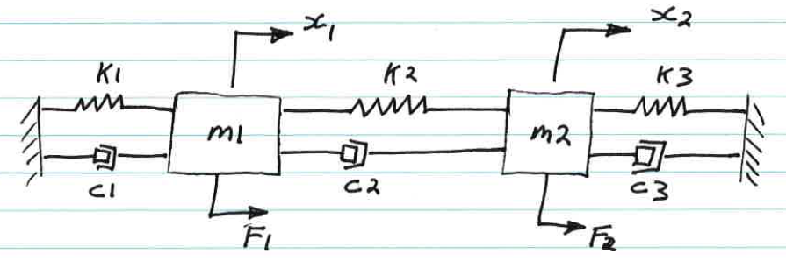 

In this tutorial we're going to look at the following subtopics:

$\qquad \bullet
$ apply Newton's laws to derive the system's dynamic equation of motion

$\qquad \bullet
$ derive the **ANALYTICAL** solution for the ZERO excitation case

$\qquad \bullet $ solve **NUMERICALLY** the solution for the ZERO excitation case

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## 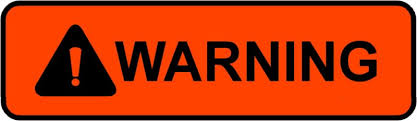

This script takes about **90 minutes** to run on my Lenovo P50 laptop.

**Model parameters:  **Note all parameters are in SI units, ie: *kg, N/m, N/(m/sec)*

We'll load in the Mechanical system parameters from a file:

params = bh_func_2dof_params()

And then locally assign to sensibly named variables:

m1 = params.m1 ;    m2 = params.m2 ; 
k1 = params.k1 ;    k2 = params.k2 ;    k3 = params.k3 ;
c1 = params.c1 ;    c2 = params.c2 ;    c3 = params.c3 ;

**Define the INITIAL conditions of the system:**

Let's consider the system with initial conditions of:

$\matrix{
\bullet \quad \dot{x}_1(0) = 0\cr
\bullet \quad \dot{x}_2(0) = 5\cr
\bullet \quad x_1(0) = 1\cr
\bullet \quad x_2(0) = -0.5\cr
}$   .

% define some INITIAL conditions for our system
init_x1dot =  0;
init_x2dot =  5;
init_x1    =  1;
init_x2    = -0.5;

**Apply Newton's law:**

The free body diagram for this system is shown below:

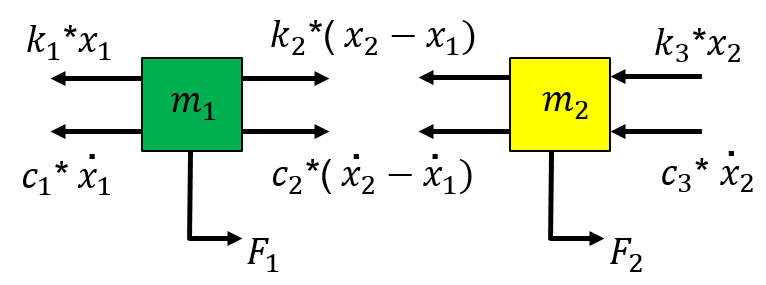

For the 1st mass we have:


$$m_1 \thinspace \ddot{x_1} = F_1 + k_2(x_2 - x_1) + c_2(\dot{x_2} - \dot{x_1}) - k_1x_1 - c_1 \dot{x_1}$$
 


$$m_1 \thinspace \ddot{x_1} = F_1  +  x_1(-k_2 + -k_1) +   x_2(k_2) +  \dot{x_1}(-c_2 + -c_1) +   \dot{x_2} (c_2) 
$$
 

For the 2nd mass we have:


$$m_2 \thinspace \ddot{x_2} = F_2 - k_2(x_2 - x_1) - c_2(\dot{x_2} - \dot{x_1}) - k_3x_2 - c_3 \dot{x_2}$$


 
$$m_2 \thinspace \ddot{x_2} = F_2  +  x_1(k_2) + x_2(-k_2 + -k_3) + \dot{x_1}(c_2) + \dot{x_2}(-c_2 + -c_3)$$


We can combine the two 2nd order ODEs into a matrix equation, ie:

$\pmatrix{
m_1 & 0 \cr
0 & m_2 \cr
}$$. \pmatrix{
\ddot{x}_1 \cr
\ddot{x}_2 \cr
}$ + $\pmatrix{
(c_1 + c_2) & -c_2 \cr
-c_2 & (c_2+c_3) \cr
}$$. \pmatrix{
\dot{x}_1 \cr
\dot{x}_2 \cr
}$ + $\pmatrix{
(k_1 + k_2) & -k_2 \cr
-k_2 & (k_2+k_3) \cr
}$$. \pmatrix{
{x}_1 \cr
{x}_2 \cr
}$= $\pmatrix{
{F}_1 \cr
{F}_2 \cr
}$

which we can refer to as:   

- $M \ddot{X} + C\dot{X} + KX = F$   where:    $X=\text{ }\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$  and   $F=\text{ }\left\lbrack \begin{array}{c}
F_1 \\
F_2 
\end{array}\right\rbrack$

So let's define our mechanical system matrices:

Mm_mat  = [  m1,      0;
              0,     m2    ];

Cm_mat  = [(c1+c2), -c2;
           -c2,    (c2+c3) ];
       
Km_mat  = [(k1+k2), -k2;
           -k2,    (k2+k3) ];
       
F       = [0;0];       

## Finding the analytical solution: - step 1

To find the analytical solution we'll convert the 2nd order system of ODEs into a new 1st order system.  

$\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$. \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

which has the form:

-  $\dot{Z} = A \times Z + G$    where:  $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and    $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$  and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

So let's define our new system matrices:

As_mat  = [-inv(Mm_mat)*Cm_mat,   -inv(Mm_mat)*Km_mat; 
                        eye(2),   zeros(2)  ];

G = [ inv(Mm_mat)*F;
      zeros(2,1) ];   

## Finding the analytical solution: - step 2

So let's use the Symbolic toolbox to find the analytical solution.

syms t x1(t) x2(t) v1(t) v2(t) z1(t) z2(t) z3(t) z4(t)
% from this moment onwards I want t to be regarded as REAL
assume(t, 'real');

v1(t)   = diff(x1,t);
v2(t)   = diff(x2,t);
XdX     = [v1(t), v2(t), x1(t), x2(t)] .';
Z       = [z1(t), z2(t), z3(t), z4(t)] .';
Zsf     = symfun(Z, t);
Z_ICs   = [ init_x1dot;
            init_x2dot; 
            init_x1;
            init_x2;  ];

So assemble the new Z ODE:   $\dot{Z} = A \times Z + G$    where:  $Z =  \pmatrix{
\dot{X} \cr
X \cr
} $

ODE_RHS  = subs( (As_mat*XdX + G), XdX, Z);
ODE_LHS  = diff(Z,t);
EQ_Z_ODE = ODE_LHS == ODE_RHS;

Define some INITIAL conditions for our system

my_ICs = Zsf(0) == Z_ICs;

Now let's solve this:  ATTENTION:  this takes 6 minutes to complete on my laptop(P50)

% now let's solve our system
the_Q_sol = dsolve(EQ_Z_ODE, my_ICs, 'IgnoreAnalyticConstraints', false)
%the_Q_sol = dsolve(EQ_Z_ODE, my_ICs)

**MESSAGE to self:**

Echoing the contents of `the_Q_sol`, eg:

`>> the_Q_sol.z1`

takes about a minute. So?  - So I'm concerned that doing other kinds of manipulations with `the_Q_sol`, such as fplot() of subs() .... will in turn take toooo long.

So? - So I decided to convert the symbolic expressions into MATLAB functions ... thinking that using the resulting MLF's would be faster.

But .... invoking matlabFunction() on the contents of the `the_Q_sol`, took about 90 minutes to do ! - SEE BELOW

## 

This section of code takes about 90 minutes to complete on my Lenovo P50

## For speed(?) let's convert to SYMS to a MATLAB function:

So let's convert the symbolic solutions into a MATLAB function:            

matlabFunction(the_Q_sol.z3, 'File','bh_x1_file');
matlabFunction(the_Q_sol.z4, 'File','bh_x2_file'); 
matlabFunction(the_Q_sol.z1, 'File','bh_x1DOT_file');
matlabFunction(the_Q_sol.z2, 'File','bh_x2DOT_file'); 


## **So let's visualize our ANALYTICAL solution:**

T_ana      = [0:0.01:5]';
X1_ana     = bh_x1_file(T_ana);
X2_ana     = bh_x2_file(T_ana);
X1_dot_ana = bh_x1DOT_file(T_ana);
X2_dot_ana = bh_x2DOT_file(T_ana);

bh_plot_2dof_response( T_ana, X1_ana,     ...
                              X2_ana,     ...
                              X1_dot_ana, ...
                              X2_dot_ana, ...
                              '-b');

# Numerical solution:

So far we've looked at finding an analytical solution to the mechanical system. An alternate approach is to solve the problem numerically. This numerical approach is extremely attractive when an analytical solution becomes difficult and/or impossible to derive.  At the heart of this approach are MATLAB's ODE solver suit - MATLAb has many ODE solver algorithms.  A good general purpose solver is the MATLAB function `ode45()` .

These numeric ODE solvers require you to package your problem into a 1st order form. We've already seen how to do this for a Mechanical system ,ie:

                      $\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$\times \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

which has the form:

                  $\dot{Z} = A \times Z + G$    where:  $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and    $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$   and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

So let's look at the example we solved previously:

% Define your INITIAL conditions
z_init = [init_x1dot;
          init_x2dot;
          init_x1;
          init_x2 ];
      
% define the system EXCITATION functions
F_fh = @(t) [ 0;
              0 ];

% define the 1st order system to solve
As_mat    = [-inv(Mm_mat)*Cm_mat,   -inv(Mm_mat)*Km_mat; 
                          eye(2),   zeros(2)  ];

G_fh      = @(t) [ inv(Mm_mat)*F_fh(t);
                 zeros(2,1) ];   

MY_SYSTEM = @(t, z) (As_mat*z + G_fh(t) );

% Define some ODE solver settings
t_span     = [0 5];
my_options = odeset('RelTol', 1e-7, 'AbsTol', 1e-7);

% use ODE45 to numerically solve your system
%[T,Y] = solver(odefun,   tspan,  z0,     options)
[~,Z]  = ode45(MY_SYSTEM, T_ana, z_init, my_options);

## Plot the NUMERIC solution:

T_num      = T_ana;
X1_dot_num = Z(:,1); 
X2_dot_num = Z(:,2);  
X1_num     = Z(:,3);  
X2_num     = Z(:,4);

% plot the responses
bh_plot_2dof_response( T_num, X1_num,     ...
                              X2_num,     ...
                              X1_dot_num, ...
                              X2_dot_num, ...
                              '-r');

# **Compare ANALYTICAL versus Numeric solutions**

**We 'll just do a visual comparison for now:**

figure;
subplot(2,2,1);
   plot(T_ana, X1_num,'-r', 'Linewidth', 2);  hold on
   plot(T_ana, X1_ana,'-b');                  bh_annotate_2dof_compare( gca, 't (secs)', 'X1 (m)')
   %----------------------------------------------------------------------- 
subplot(2,2,2);
   plot(T_ana, X2_num,'-r', 'Linewidth', 2);  hold on
   plot(T_ana, X2_ana,'-b');                  bh_annotate_2dof_compare( gca, 't (secs)', 'X2 (m)') 
   %----------------------------------------------------------------------- 
subplot(2,2,3);
   plot(T_ana, X1_dot_num,'-r', 'Linewidth', 2);  hold on
   plot(T_ana, X1_dot_ana, '-b');                 bh_annotate_2dof_compare( gca, 't (secs)', 'X1 dot (m/sec)') 
   %----------------------------------------------------------------------- 
subplot(2,2,4);
   plot(T_ana, X2_dot_num,'-r', 'Linewidth', 2);  hold on
   plot(T_ana, X2_dot_ana,'-b');                  bh_annotate_2dof_compare( gca, 't (secs)', 'X2 dot (m/sec)')                           